# Risposte per i test Cap 8

## Capitoli del libro

### Derivazione numerica

#### Differenze finite in avanti

#### Differenze finite all'indietro

#### Differenze finite centrate

#### Differenze finite centrate per derivata seconda

### EDO e sistemi di EDO del primo ordine

Funzione migliore integrata in matlab per risolvere le edo: [t,y] = ode45(odefun,tspan,y0)

#### Metodo di Eulero in avanti

#### Metodo di Eulero all'indietro

#### Metodo di Crank-Nicolson

#### Metodo di Heun

#### Metodi di Runge-Kutta

#### Metodi multipasso

#### θ-Metodo

### Edo del secondo ordine

### Edo di ordine superiore a 2

## Utile in generale

### Assoluta stabilità EA, EI, C-K, Heun

vedi Stabilita_Assoluta_A5.pdf

### Stima dell'errore

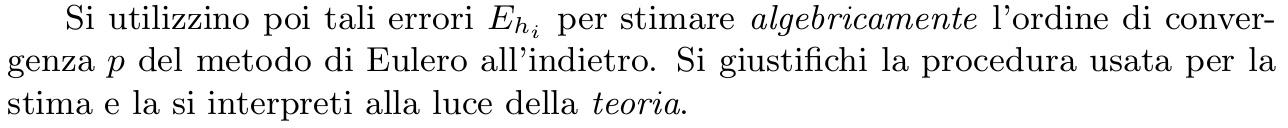

usa polyfit

% h → vettore contenente tutti i passi
% E_h → vettore contenente i relativi errori
p = polyfit(log(h), log(E_h'), 1);

Giustificazione teorica: Il metodo di integrazione usato ha un certo ordine di convergenza p, quindi l'errore globale si comporta asintoticamente come E_h = C*h^p. Passando ai logaritmi si ottiene log(E_h) = p*log(h) + log(C), cioe' una relazione lineare tra log(E_h) e log(h) con pendenza pari all'ordine p. Calcolando gli errori E_h per una successione di passi h via via piu' piccoli e stimando tale pendenza tramite regressione lineare ai minimi quadrati, si ricava il valore di p. Tale valore risulta prossimo all'ordine teorico atteso del metodo, e l'eventuale lieve deviazione e' dovuta ai termini di ordine superiore nell'espansione dell'errore, trascurabili solo nel limite h -> 0.